# Ladder Problem

Find the EOM for a ladder sliding down a vertical wall. Use event triggers to change the EOM when the ladder leaves the vertical surface and another to stop the integration when the laddder hits the floor.

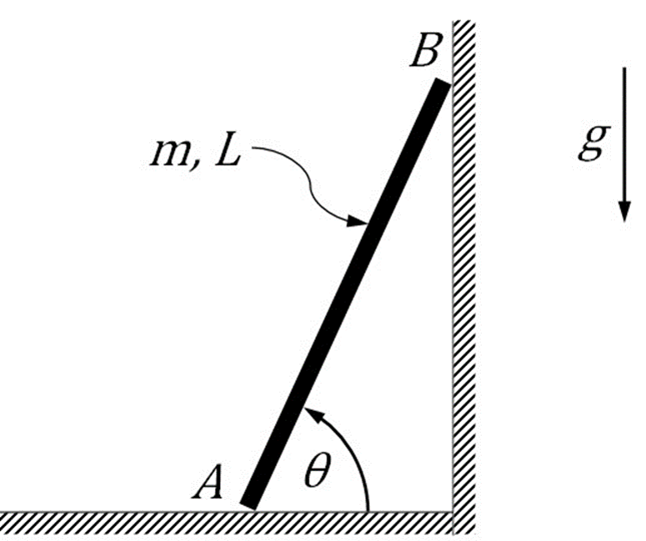

1 DOF $\theta \rightarrow$1 EOM $\ddot{\theta}$

Solve for when point B leaves the surface, i.e. $N_B = 0$

No friction or other losses

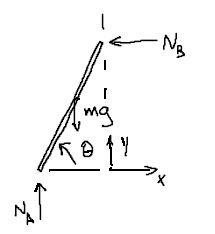

clc
clear
syms m xddotcm NB yddotcm NA g L thetaddot theta thetadot

## Part 1: Ladder in contact with vertical wall.

eqn(1) = m*xddotcm == -NB;
eqn(2) = m*yddotcm == NA-m*g;
eqn(3) = (1/12*m*L^2)*thetaddot == -NA*L/2*cos(theta)+NB*L/2*sin(theta);
eqn(4) = yddotcm == L/2*thetaddot*cos(theta)-L/2*thetadot^2*sin(theta);
eqn(5) = xddotcm == L/2*thetaddot*sin(theta)+L/2*thetadot^2*cos(theta);
unknowns = solve(eqn,[xddotcm,yddotcm,thetaddot,NA,NB]);
tdd = simplify(unknowns.thetaddot)

$$tdd = -\frac{3\,g\,\cos\left(\theta \right)}{2\,L}$$


$$\ddot{\theta} = \frac{-3g}{2L}\cos(\theta)$$


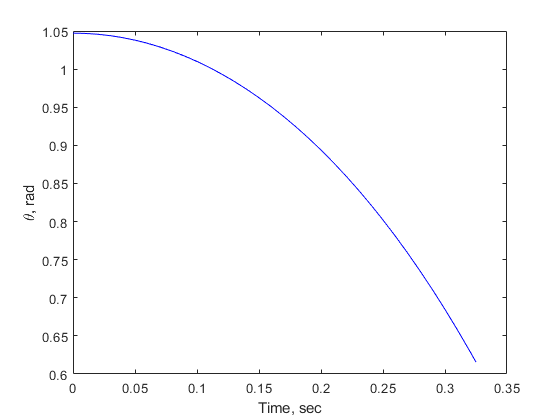

syms theta(t) thetadot(t)
eom = odeFunction([thetadot;unknowns.thetaddot],[theta;thetadot],g,L);
NBfunc = odeFunction(unknowns.NB,[theta;thetadot],m,g,L); % create function to evaluate NB
mn = 2; % kg
gn = 9.81; % m/s^2
Ln = 1; % m
options = odeset('Events',@(t,s)event(t,s,NBfunc,mn,gn,Ln)); % stop integration when NB=0
[T,S,TE,SE,IE] = ode45(@(t,s)eom(t,s,gn,Ln),linspace(0,2,201),[pi/3,0],options);
plot(T,S(:,1),'-b')
xlabel('Time, sec')
ylabel('\theta, rad')

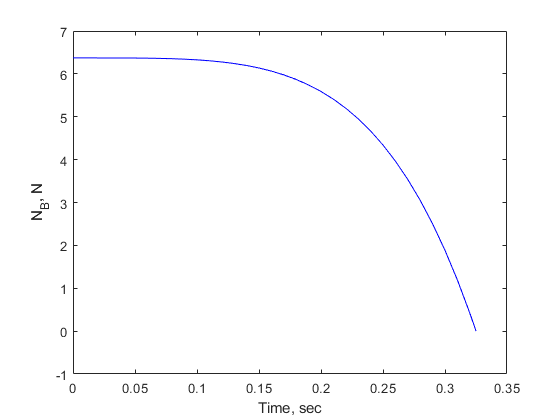

NBplot = NBfunc(T,S',mn,gn,Ln);
figure
plot(T,NBplot,'-b')
xlabel('Time, sec')
ylabel('N_B, N')

## Part 2: Ladder no longer in contact with vertical wall.

eqn = subs(eqn,NB,0);
unknowns2 = solve(eqn(1:4),[xddotcm,yddotcm,thetaddot,NA]);


$$\ddot{\theta}=-\frac{3\cos{\theta}}{L(1+3\cos^2{\theta})}\left(2g-L\dot{\theta}^2\sin{\theta}\right)
\\
\ddot{x} = 0$$


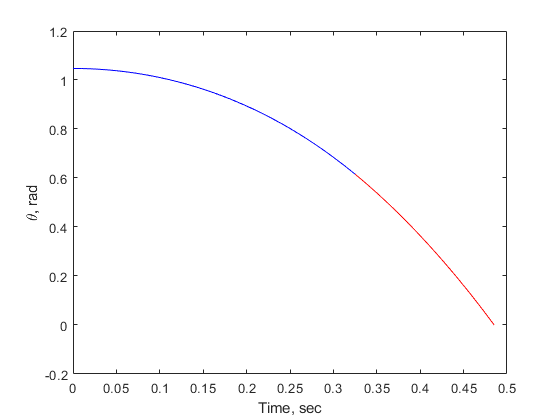

syms xcm(t) xdotcm(t)
eom2 = odeFunction([thetadot;unknowns2.thetaddot;xdotcm;unknowns2.xddotcm],...
    [theta;thetadot;xcm;xdotcm],g,L);
[T2,S2,TE2,SE2,IE2] = ode45(@(t,s)eom2(t,s,gn,Ln),linspace(TE,2,201),...
    [SE,-Ln/2*cos(SE(1)),Ln/2*SE(2)*sin(SE(1))],options);
figure
plot(T,S(:,1),'-b',T2,S2(:,1),'-r')
xlabel('Time, sec')
ylabel('\theta, rad')

clear theta(t) thetadot(t)
syms theta thetadot
u = symunit;
m = m*u.kg;
g = g*u.m/u.sec^2;
L = L*u.m;
xddotcm = xddotcm*u.m/u.sec^2;
yddotcm = yddotcm*u.m/u.sec^2;
thetaddot = thetaddot/u.sec^2;
thetadot = thetadot/u.sec;
NA = NA*u.N;
NB = NB*u.N;
eqn = subs(eqn);
checkUnits(eqn)

ans = struct with fields:
    Consistent: [1 1 1 1 1]
    Compatible: [1 1 1 1 1]


[~,Units]=separateUnits(eqn)

$$Units = \left(\begin{array}{ccccc} 1\,\frac{\mathrm{kg}\,m}{s^{2}} & 1\,\frac{\mathrm{kg}\,m}{s^{2}} & 1\,\frac{\mathrm{kg}\,m^{2}}{s^{2}} & 1\,\frac{m}{s^{2}} & 1\,\frac{m}{s^{2}} \end{array}\right)$$

AccelEOM = subs([unknowns.thetaddot;unknowns2.thetaddot]);
[~,Units] = separateUnits(AccelEOM)

$$Units = \left(\begin{array}{c} \frac{1}{s^{2}}\\ \frac{1}{s^{2}} \end{array}\right)$$

subfunction

function [value,isterminal,direction] = event(t,s,NBfunc,mn,gn,Ln)
value(1) = NBfunc(t,s,mn,gn,Ln); % current normal force at B
isterminal(1) = 1; % stop integration
direction(1) = -1; % negative slope
value(2) = s(1); % theta = 0, hits horizontal surface
isterminal(2) = 1; % stop integration
direction(2) = -1; % negative slope
end